# **EXPERIMENT 5**

### **NAME: RAHIL SHARMA **

### **PRN: 18070123062 **

### **BATCH: EA-3**

**AIM: To simulate and observe the Rayleigh Distribution. Then get a brief understanding on the concept of Rayleigh Fading.**

**THEORY: **The Rayleigh fading model uses a statistical approach to analyse the propagation, and can be used in a number of environments. The Rayleigh fading model is ideally suited to situations where there are large numbers of signal paths and reflections. Typical scenarios include cellular telecommunications where there are large number of reflections from buildings and the like and also HF ionospheric communications where the uneven nature of the ionosphere means that the overall signal can arrive having taken many different paths. 

- Characterizing Amplitude fluctuations:Consider a transmitter (Base station) and   receiver   (mobile)   in   a   city   environment.   The   medium   between   the transmitter  and  receiver  are  obstructed  by  several  buildings,  trees  and  other objects. The receiver keeps moving away from the transmitter. We measure the signal  power  at  the  receiver  as  we  move  away  from  the  receiver.  The  ratio  of received  signal  power  to  the  transmitted  signal  power  is  plotted  against  the distance

- Multi-path Fading: A signal travelling in an environment may get reflected by several  objects  on  the  path.  This  gives  rise  to  several  reflected  signals.  The reflected  signals  arrive  at  the  receiver  at  different  time  instants  and  with different  intensities  leading  to  multipath  propagation.  Depending  on  the  phase of  each  individual  reflected  signal,  the  received  signal  power  may  increase  or decrease due to contructive or destructive interference. A small variation in the phase  of  each  reflected  signal  from  each  multipath  may  lead  to  significant difference  in  the  total  received  power.  This  phenomenon  is  also  referred  as short-term or small scale fading.

- Characterizing   amplitude   fluctuations:Three phenomenon’s namely :  1) Propagation  path  loss  2)  Shadowing/large  scale  fading 3)  Multipath  or  small scale  fading  contribute  to  amplitude  fluctuations  in  the  received  signal.  It  is often desirable to characterize the amplitude fluctuations statistically. 

**CODE OF THE PROGRAM AND IT'S OUTPUTS:**

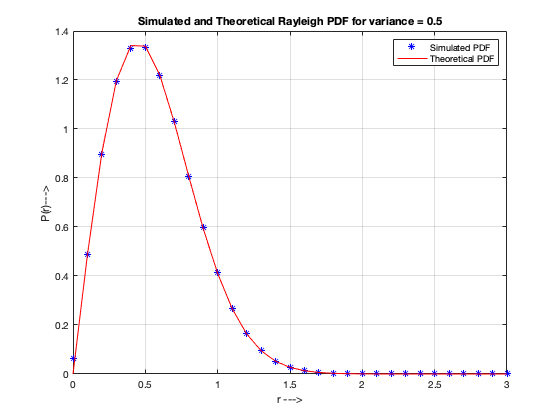

%----Rayleigh_PDF-----------------------------------------  

%----------Input Section----------------  

N=1000000; %Number of samples to generate  

variance = 0.2; % Variance of underlying Gaussian random variables  

%Independent Gaussian random variables with zero mean and unit variance  

x = randn(1, N);  

y = randn(1, N);  

 

%Rayleigh fading envelope with the desired variance 

r = sqrt(variance*(x.^2 + y.^2));  

%Define bin steps and range for histogram plotting  

step = 0.1; range = 0:step:3;  

 

%Get histogram values and approximate it to get the pdf curve  

h = hist(r, range);  

approxPDF = h/(step*sum(h)); %Simulated PDF from the x and y samples  

 

%Theoritical PDF from the Rayleigh Fading equation  

theoretical = (range/variance).*exp(-range.^2/(2*variance));  

plot(range, approxPDF,'b*', range, theoretical,'r');  

title('Simulated and Theoretical Rayleigh PDF for variance = 0.5')  

legend('Simulated PDF','Theoretical PDF')  

xlabel('r --->');  

ylabel('P(r)---> '); 

grid;  

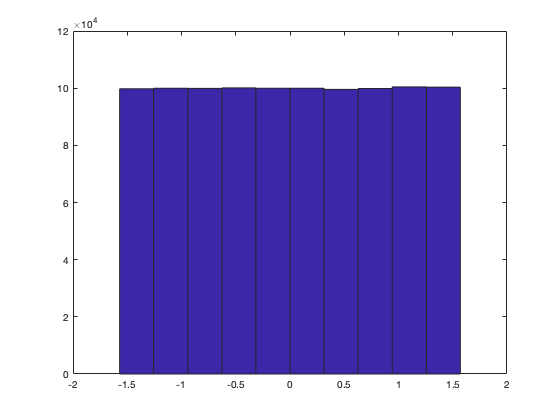


  

%PDF of phase of the Rayleigh envelope  

theta = atan(y./x);  

figure(2)  

hist(theta); %Plot  histogram of the phase part  

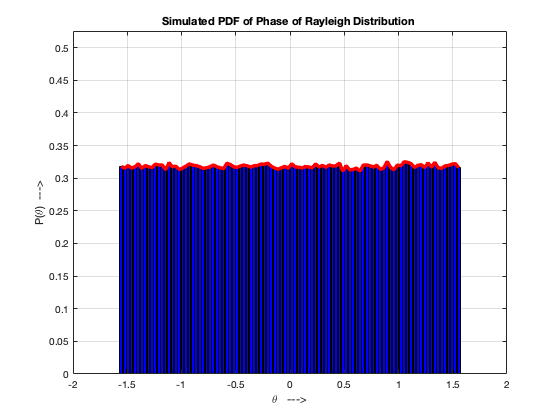


 

%Approximate the histogram of the phase part to a nice PDF curve  

[counts,range] = hist(theta,100);  

step=range(2)-range(1);  

 

%Normalizing the PDF to match theoretical curve  

approxPDF = counts/(step*sum(counts)); %Simulated PDF from the x and y samples  

bar(range, approxPDF,'b');  

hold on  

plotHandle=plot(range, approxPDF,'r');  

set(plotHandle,'LineWidth',3.5); 

axis([-2 2 0 max(approxPDF)+0.2]) 

hold off 

title('Simulated PDF of Phase of Rayleigh Distribution ');  

xlabel('\theta   --->');  

ylabel('P(\theta)  --->'); 

grid;

**RESULT: **Amplitude Flunctuations can be observed in our Outputs. Amplitude Flunctuations are mainly of two types:

**Characterizing   Dispersion   in   Time:** In   a   multipath   environment,   the transmitted signal is reflected and scattered along the way by several obstacles. This  leads  to  the  phenomena  called –―Dispersion in Time‖ orequivalently ―frequency selectivity‖. If received signal arrives with different delays, it leads to time-dispersion of the transmitted signal. This is best characterized by Power Delay  Profile  or  PDP.  Two  scalars  namely  Delay  spread  and  coherence bandwidth are derived from the PDP.

**Rayleigh  Fading  and  Rayleigh  Distribution**: The  delays  associated  with different signal paths in a multipath fading channel change in an unpredictable manner  and  can  only  be  characterized  statistically.  When  there  are  a  large number  of  paths,  the  central  limit  theorem  can  be  applied  to  model  the  time-variant impulse response of the channel as a complex-valued Gaussian random process. When the impulse response is modeled as a zero-mean complex-valued Gaussian process, the channel is said to be a Rayleigh fading channel.

**These phemnomenos are mainly employed in applications such as wireless communication and cellular communications.**

**CONCLUSION: From this experiment we have gained a sound understanding over the concept of RAYLEIGH FADING AND RAYLEIGH DISTRIBUTION. We have also learned to plot the outputs of these on Matlab. **